# AES learning Scientific Computing with Matlab by 

Prof. Joseph Morlier

## 0. Summary

1. Defining scalar  variables

2. Vector operations

3. Matrices operation

4. For Loop

5. More programming 

6. Optimization

BONUS : Numerical integration in 2D

7. Eigenvalues and Eigenvectors

8. 2D Laplace Equation (analytical)

9. 2D Laplace Equation using 2D FD (Jacobi)

10. 1D Boundary Value Problem (1D FD)

BONUS SVD Example

## 7. Eigenvalues and Eigenvectors (a)                                                                                    

**Commands : eig **: Returns eigenvalues and eigenvectors

Let's assume this MK dynamical system with mi masses, ki springs

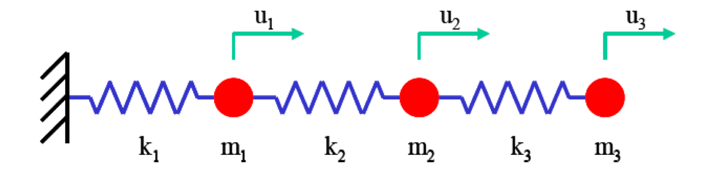

Each degree of freedom ui of the system is associated with each masses mi

Compute the eigen values (natural frequencies) and associated eigen vectors (modeshapes normalized with maximal component == 1) with this values:

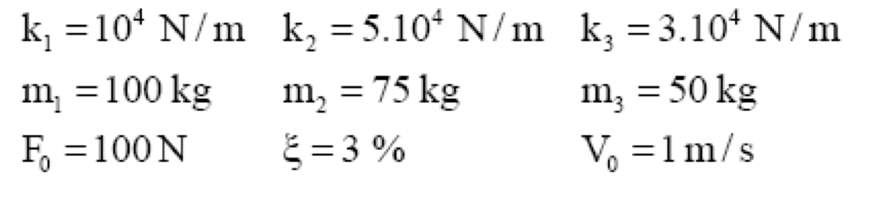

Write First the Lagrangian to extract M and K

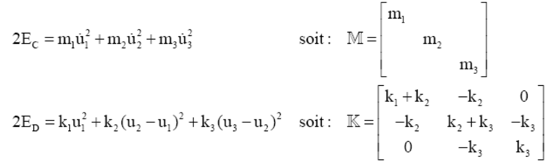

clear all; 
% springs

## 7. Eigenvalues and Eigenvectors     (b)                                                                               

**Commands : eig **: Returns eigenvalues and eigenvectors

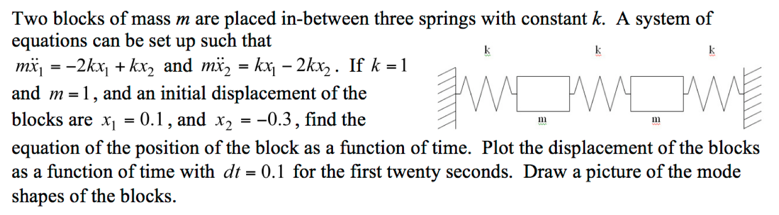

*Note*: The negative sign means that the block is displaced to the left. First mode in phase, Second mode in phase opposition.

clear all; 
% Initialize constants and matrix
m = 1;
k = 1;
A = [-2*k/m,k/m; k/m,-2*k/m]; % Calculate and display eigenvectors and eigenvalues 
[Q,d] = eig(A)
% Calculate constant C
x0 = [0.1;-0.3];
C = inv(Q)*x0;
% Calculate and plot motion of block
t = linspace(0,20,200); w=sqrt(-d);

Q =     0.7071    0.7071
   -0.7071    0.7071


d =     -3     0
     0    -1


x = C(1)*Q(:,1)*cos(w(1,1)*t) + C(2)*Q(:,2)*cos(w(2,2)*t); 
figure;
plot(t,x,'LineWidth',5);title('Displacement of blocks as a function of time');
xlabel('Time');ylabel('Displacement');legend('x1','x2');

## 8. ODE (a)

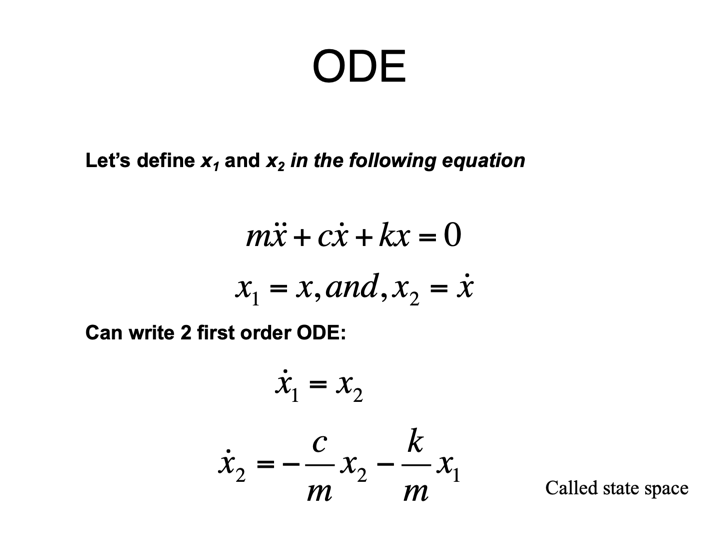

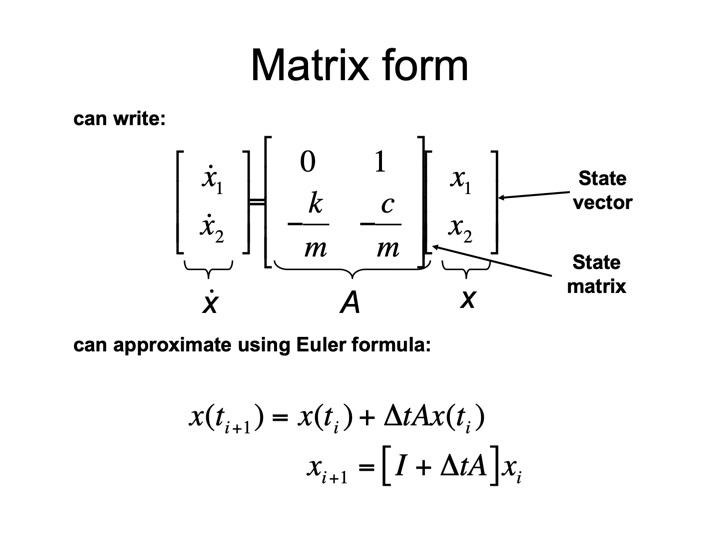

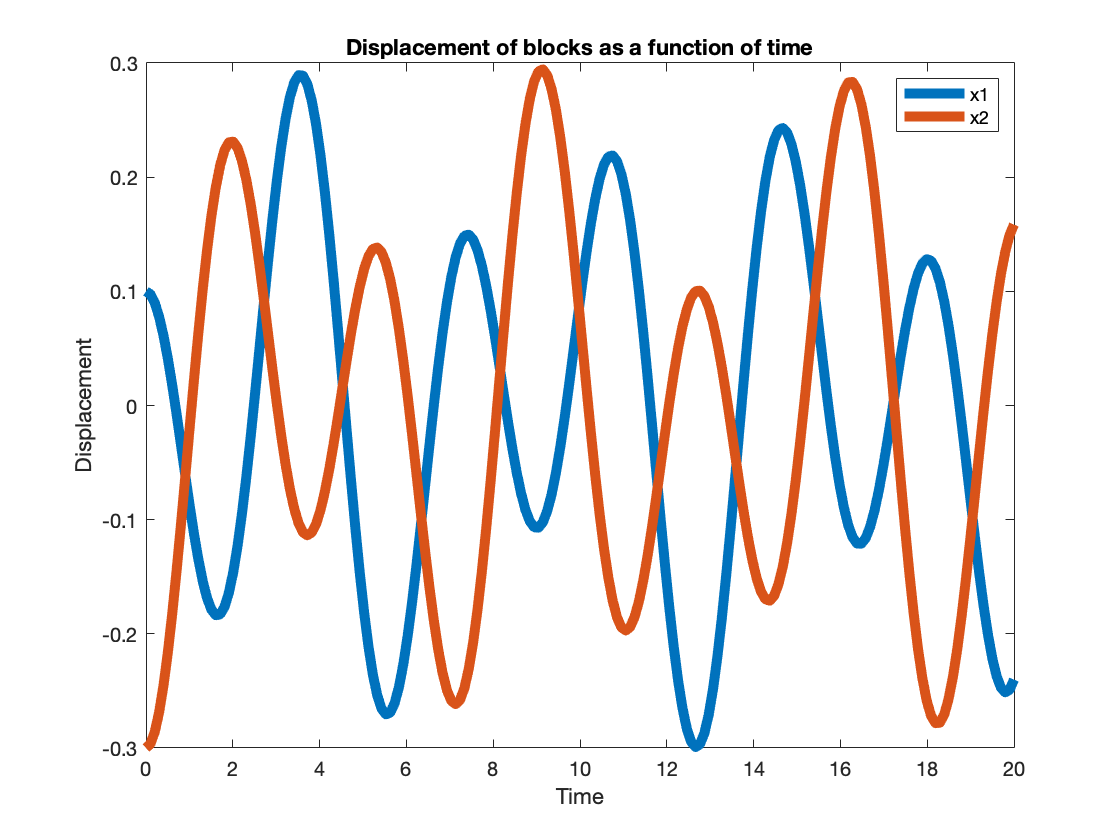

clear all; 
% play around with different 'd' and 'dt' to see various behavior!

k=2;c=1;m=3;



% spring-mass-damper system
A=[0 1;-k/m -c/m]; % \dot{x} = Ax

dt = 0.1;  % time step
T = 20;     % amount of time to integrate

x0 = [2; 0]; % initial condition (x=2, v=0)

% iterate forward Euler
%????

% compute better integral using built-in Matlab code
% 4th-order Runge Kutta 
% [TOUT,YOUT] = ODE45(ODEFUN,TSPAN,Y0)
[t,xGood] = ode45( @(t,x) A*x, 0:dt:T, x0); % 
% using function handle to define @(t,x) A*x... right-hand side
% of \dot{x} = Ax... ode45 wants us to include time in @(t,x), in 
% case there is time dependence.
hold on
plot(t,xGood(:,1),'r');%diplacement
hold on;
plot(t,xGood(:,2),'r+');%speed
legend('Forward Euler','Backward Euler','ODE45 (RK4)')

Why ODE seems better? help ODE45

## 8.ODE with external force

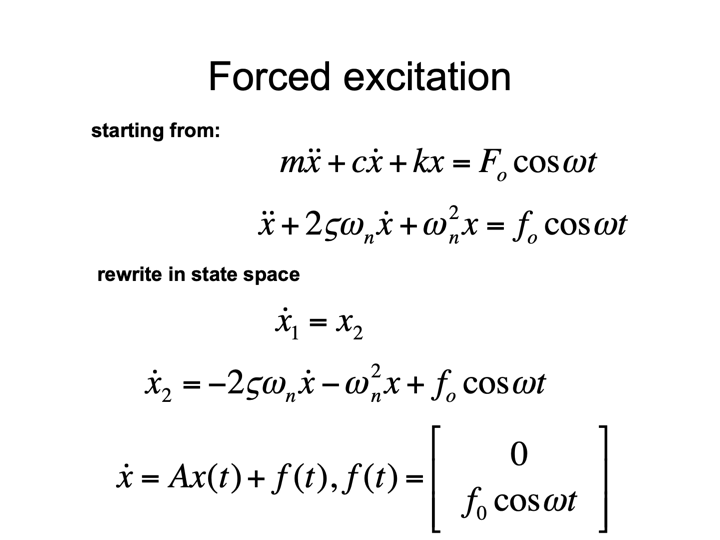

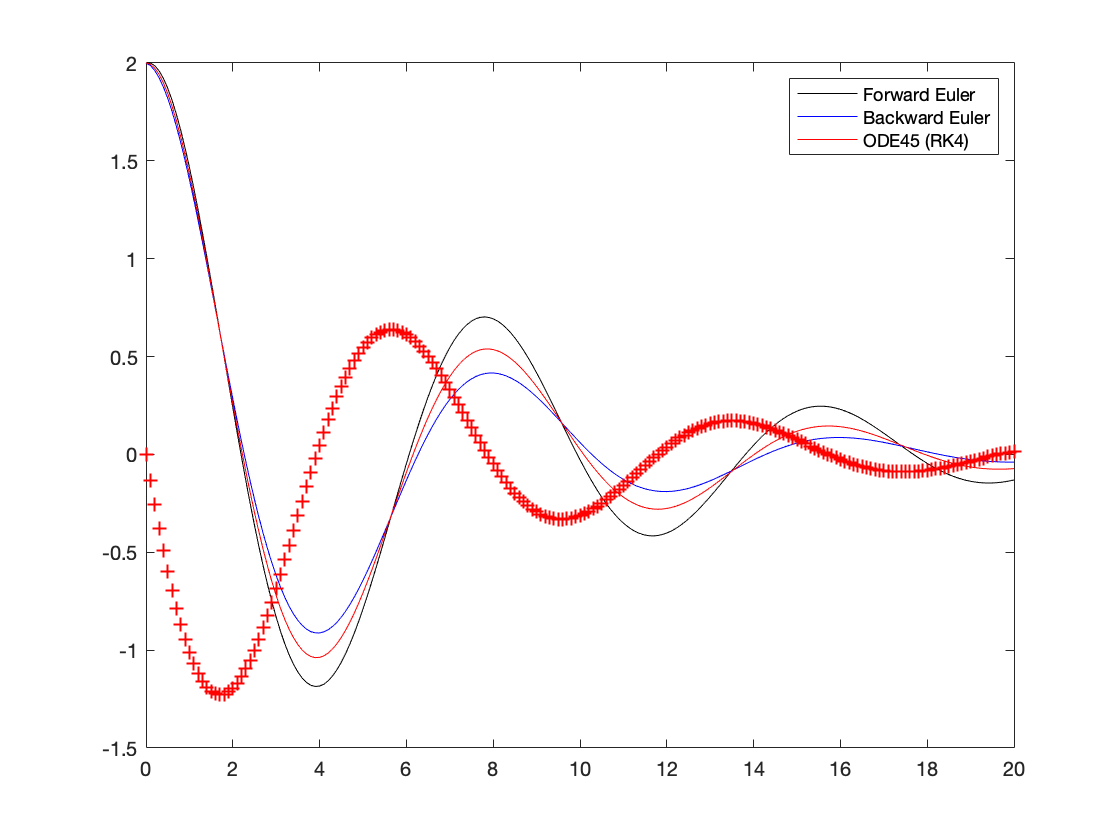

clear all;
% play around with different 'd' and 'dt' to see various behavior!

m=100;k=1000;c=25;
ze=c/(2*sqrt(k*m));

wn=sqrt(k/m);
w=2.5;F=1000;



dt = 0.1;  % time step
T = 10;     % amount of time to integrate
t=0:dt:T;

x0 = [0; 0]; % initial condition (x=0, v=0)
A=[0 1;-wn*wn -2*ze*wn];%\dot{x} = Ax+f

% compute better integral using built-in Matlab code
% 4th-order Runge Kutta 
% [TOUT,YOUT] = ODE45(ODEFUN,TSPAN,Y0)
[t,xGood] = ode45( @(t,x) A*x+[0 ;(F/m)*cos(w*t)], t, x0); % 
% using function handle to define @(t,x) A*x... right-hand side
% of \dot{x} = Ax... ode45 wants us to include time in @(t,x), in 
% case there is time dependence.
figure;
plot(t,xGood(:,1),'r');%diplacement
hold on;
plot(t,xGood(:,2),'r+');%speed
legend('ODE45 (RK4)')

## 9. 2D Laplace Equation (a)

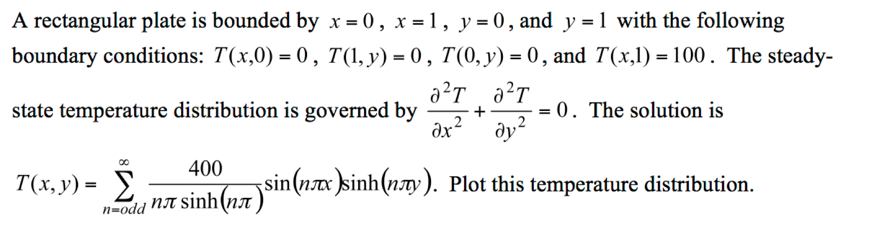

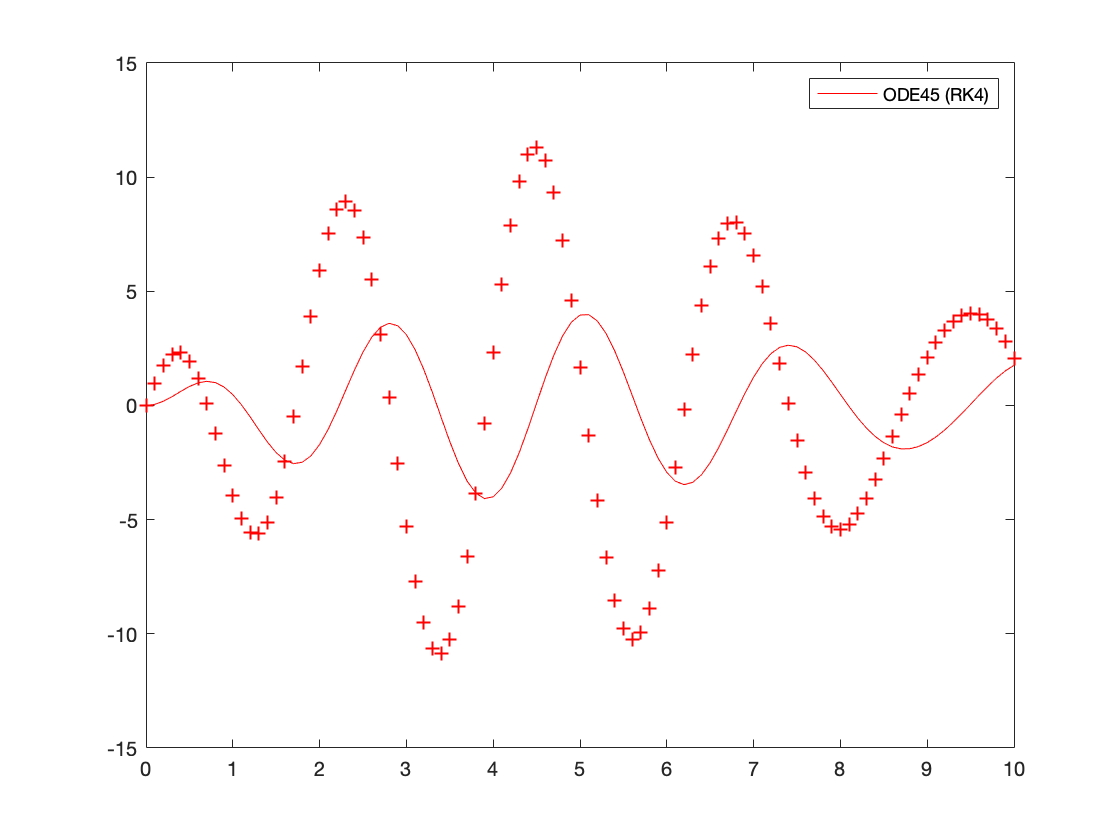

clear all; 
% Initialize square grid
[x,y] = meshgrid(0:0.01:1,0:0.01:1);
% Set maximum number of partial sums
nmax = 9;

% Initialize T
T = zeros(length(x),length(y));
% Calculate steady state temperature distribution 
for n = 1:2:nmax
T = T + 400/pi .* sinh(n*pi*y)/(n*sinh(n*pi)) .* sin(n*pi*x);
end
% Plot temperature distribution
figure;
surface(x,y,T);shading('interp')

## 9. 2D Laplace Equation using Jacobi (b)

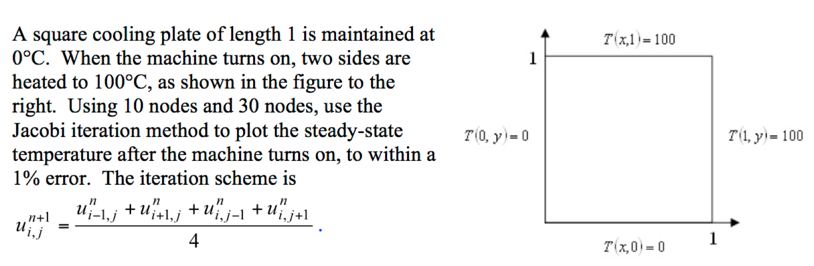

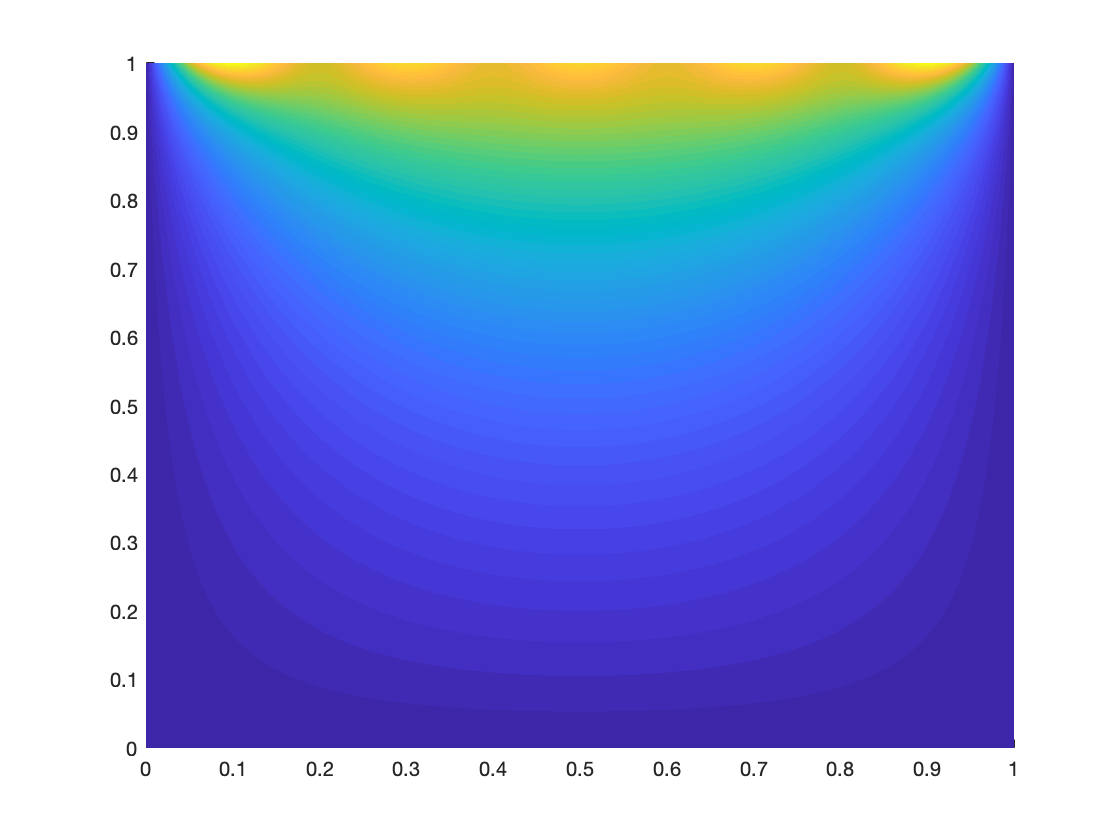

 clear all; 
% Initialize number of nodes
M = 10;
N = 10;
% Initialize function
u = zeros(M,N);
% Initialize boundary conditions 
u(M,:) = 100;

%u(:,N) = 100;
u(:,N) = 0; see analytical example
% Calculate temperature distribution
%using jacobi

## 10. BVP

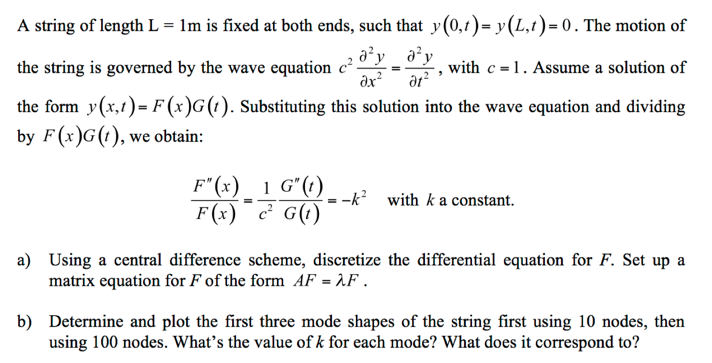

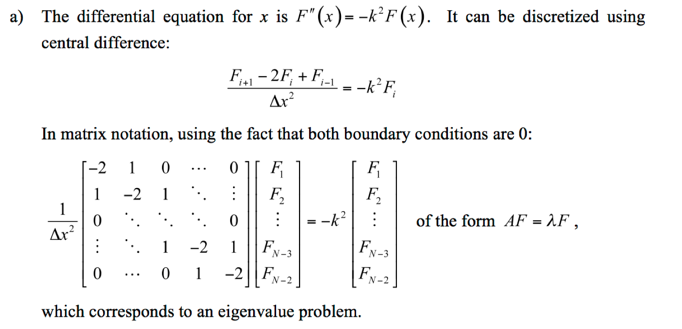

clear all ;
% Boundaries

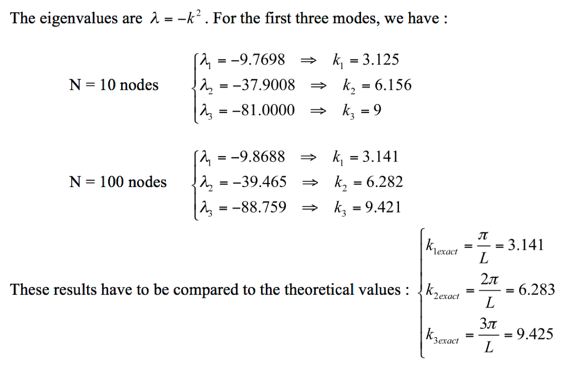

k represents the angular frequency in radian per second with which the modes oscillate in space. The more points there are, the closest from the theoretical results the numerical values are.

## BONUS Image compression using SVD

Learn how to reduce the amount of storage needed for an image using the singular value decomposition.

Approximation of A


$$\tilde A = U_k \Sigma_k V_k^T = \sum_{i=1}^{k}\sigma_i u_i \upsilon_i^T \qquad (k \leq r)$$


load('spaceshuttle.mat');
g = rgb2gray(w);                    % convert rgb to gray

subplot(1,2,1), imshow(w)
subplot(1,2,2), imshow(g)

usage: see(mat)



A = double(g);                      % uint8 -> double
[U,S,V] = svd(A,0);                 % reduced SVD
%plot -s 560,420
sig_val = diag(S);
figure; stem(sig_val(1:30));  title('Singular Values')

Approximate with k=30

k = 30;                 % low rank approximation

low_U = U(:,1:k);
low_S = S(1:k,1:k);
low_V = V(:,1:k);

A_approx = low_U*low_S*low_V';

figure; imshow(uint8(A_approx));

approximate with different low rank k

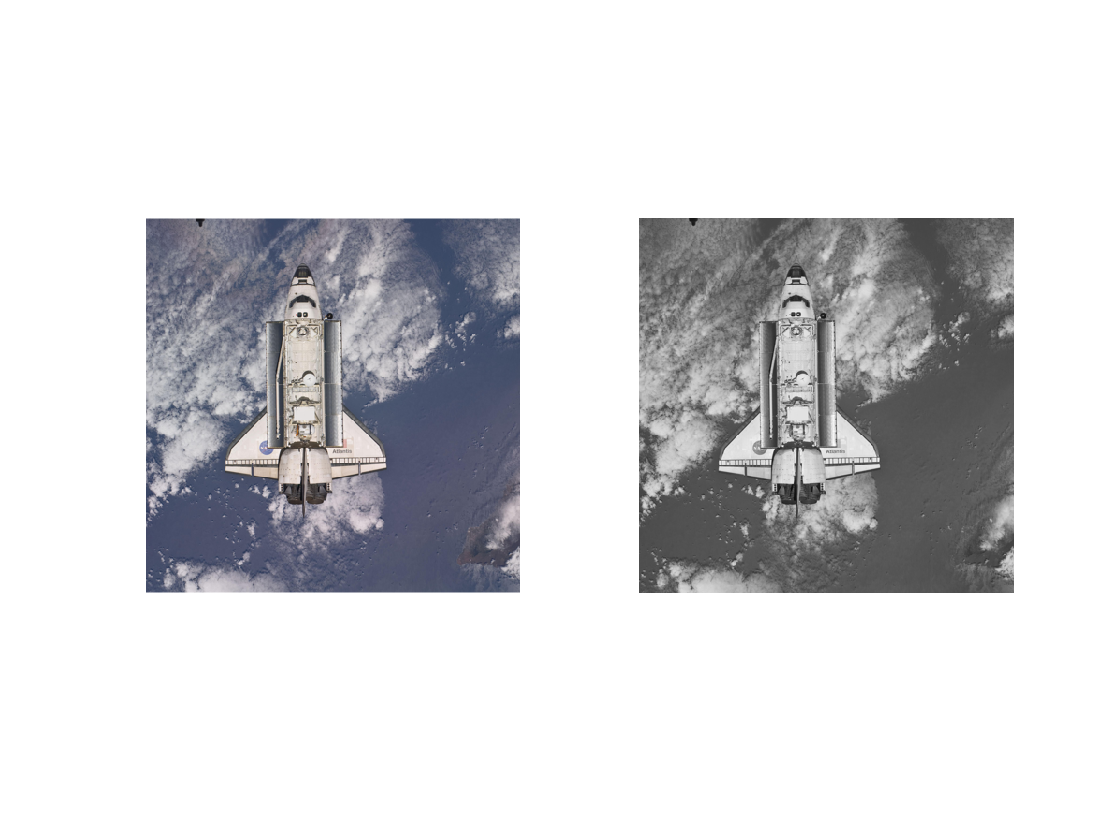

%plot -s 800,600
K = [0 1 2 3 8 10 20 30];


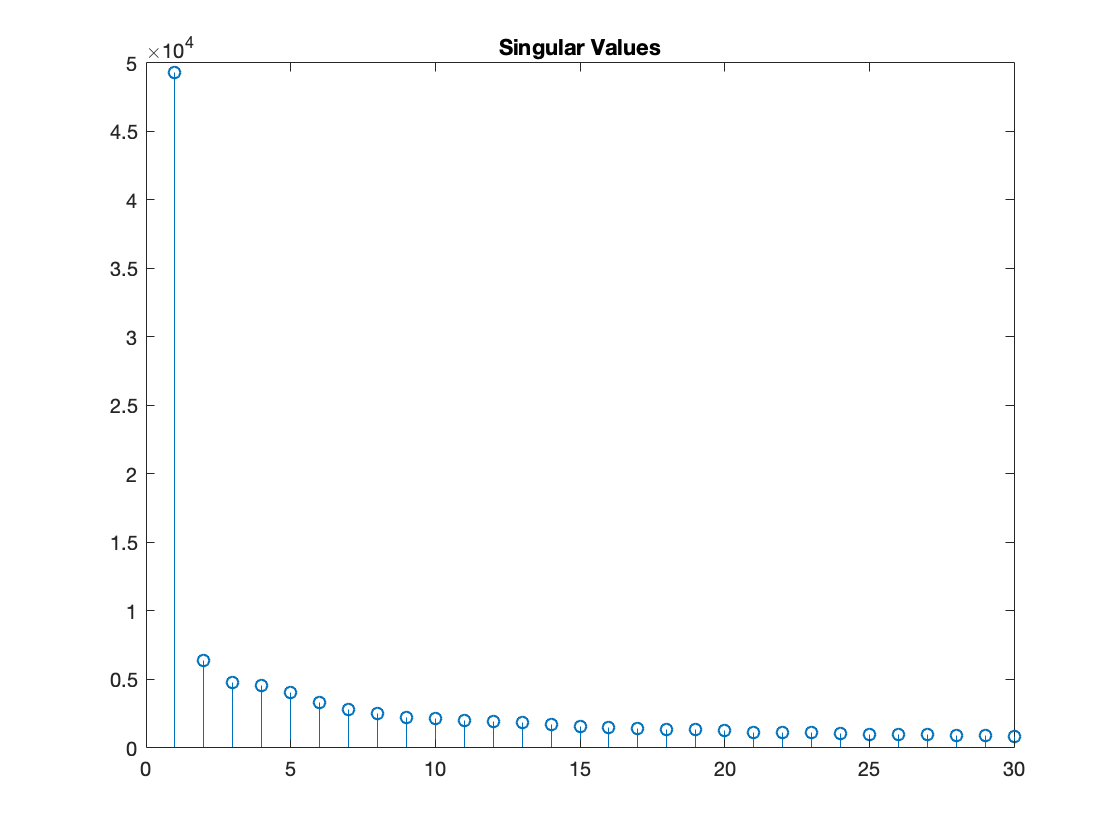

figure;

subplot(2,4,1), imshow(g);  title('rank 400','fontsize',8)

for i = 2:length(K)
    low_U = U(:,1:K(i));

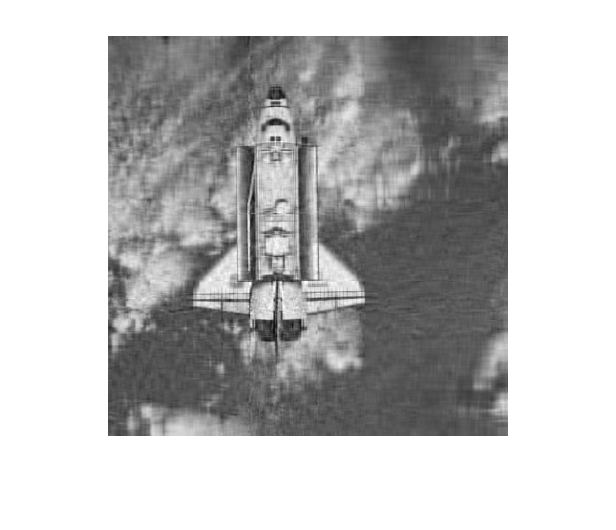

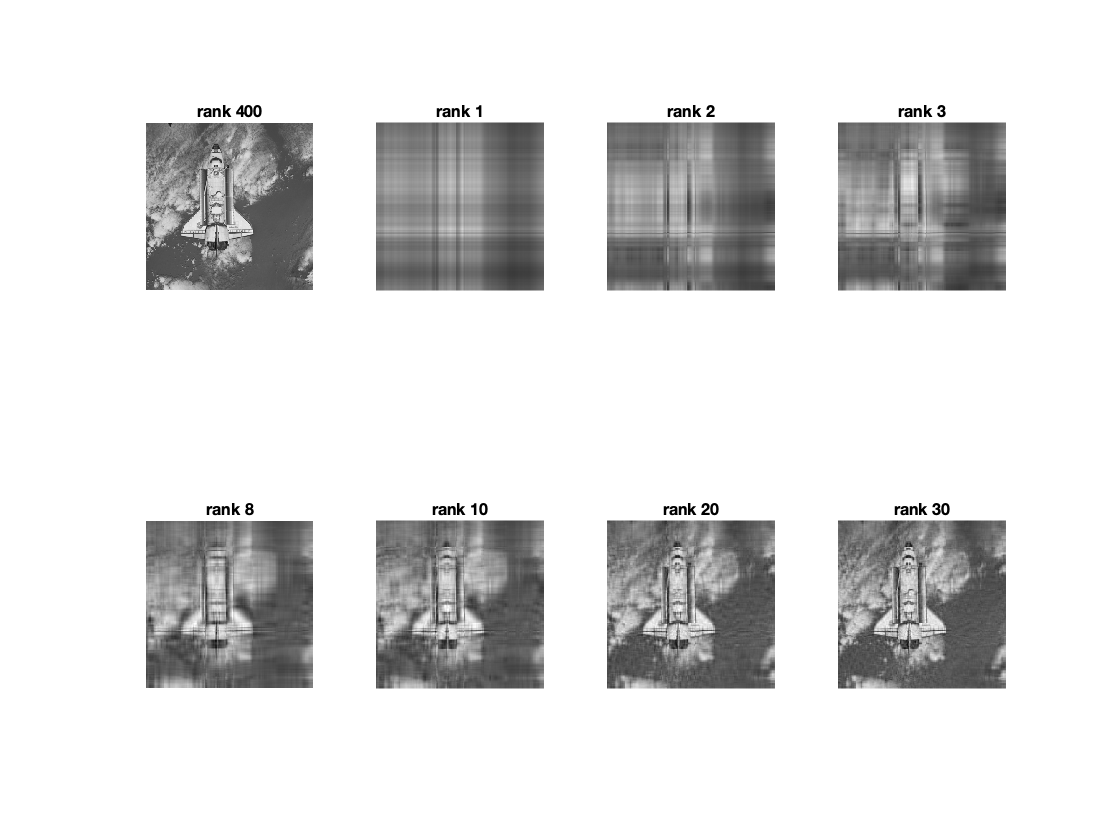

    low_S = S(1:K(i),1:K(i));
    low_V = V(:,1:K(i));

    A_approx = low_U*low_S*low_V';

    subplot(2,4,i)
    imshow(uint8(A_approx));
    title(['rank ',num2str(K(i))],'fontsize',8)
end